Esercizio 1

f=@(x) x.*atan(x)./(2*(exp(x.^2-1)-x+1));
g=@(x) (x.^2/6-1)*cos(2*x);
hold on
fplot(f,[-1 3])
fplot(g,[-1 3])

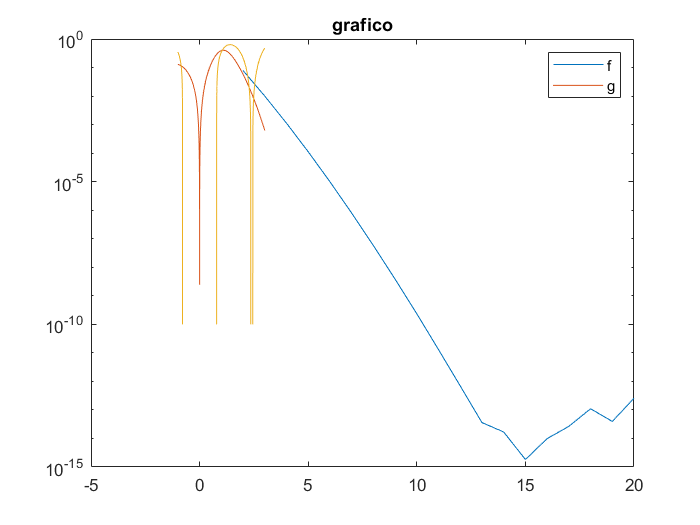

legend("f","g")

Esercizio 2

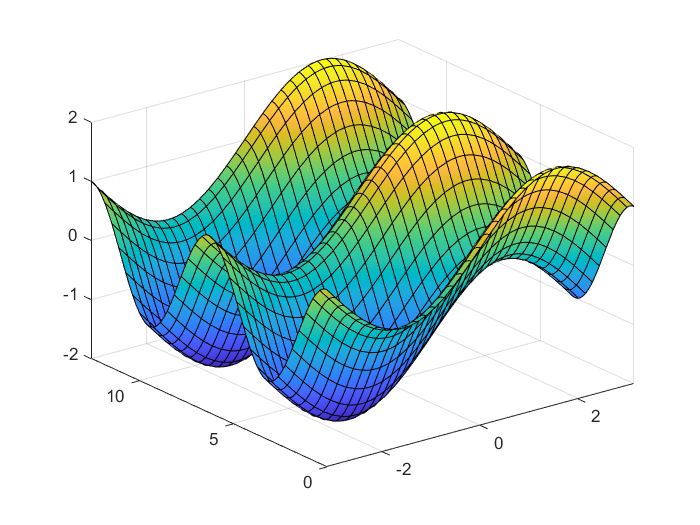

figure()
f=@(x,y) sin(x)+cos(y);
fsurf(f,[-pi pi 0 4*pi])

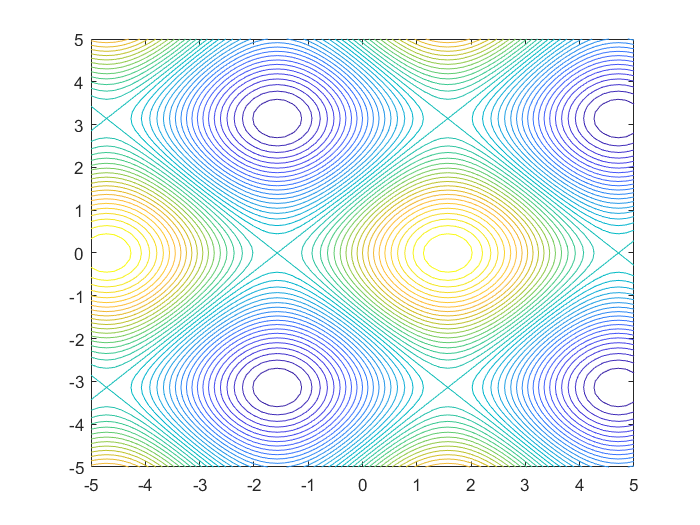

fcontour(f,"LevelStep",0.1)

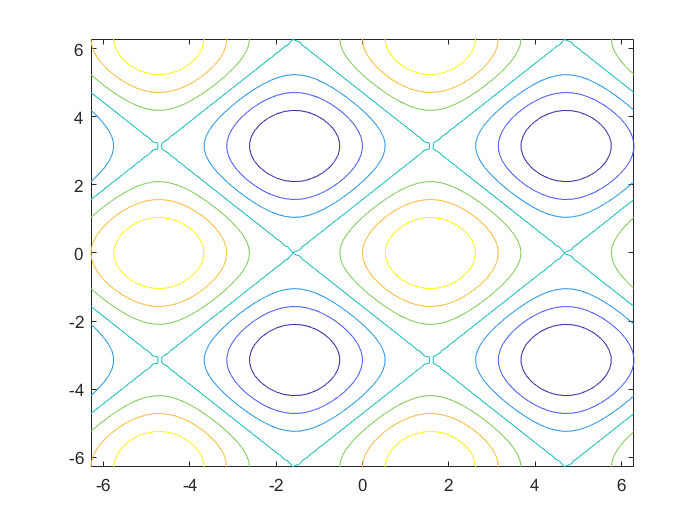

fcontour(f,[-2*pi 2*pi])

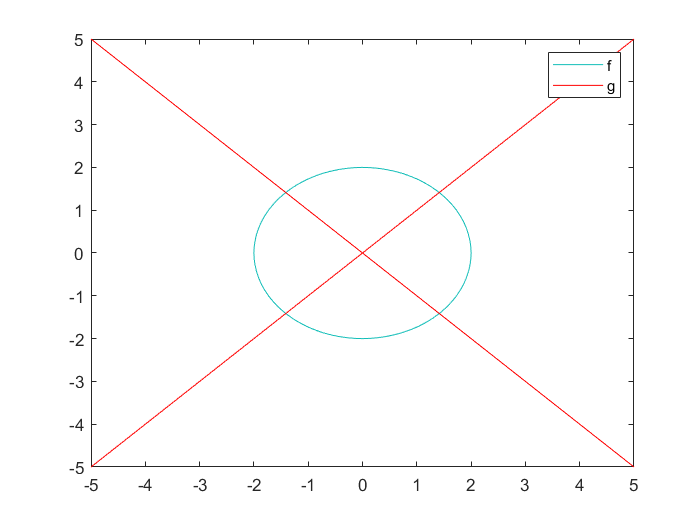

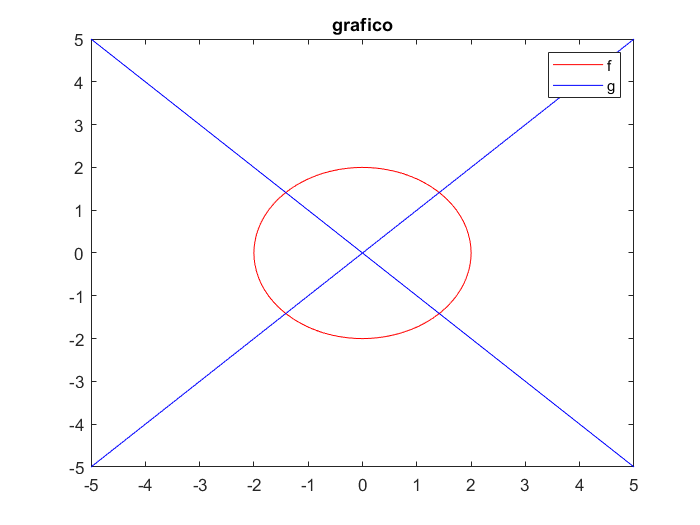

f=@(x,y) x.^2+y.^2-4;
g=@(x,y) x.^2-y.^2;
fcontour(f,"LevelList",0)
hold on
fcontour(g,"LevelList",0,"LineColor","r")
legend("f","g")
fcontourSave({f,g},0,"grafico",["f","g"],["r","b"],["LevelList","LevelList"],[0,0])

Esercizio 3

a=2; b=-3; c=1;
solveEQ2g(a,b,c)

ans =     0.5000    1.0000


delta=b^2-4*a*c;
if(delta>0)
    x1=(-b+sqrt(delta))/2*a
    x2=(-b-sqrt(delta))/2*a
elseif(delta==0)
    x=b/2*a
else
    "immaginari"
end

x1 = 4

x2 = 2

a=4; b=4; c=1;
solveEQ2g(a,b,c)

ans = -0.5000

delta=b^2-4*a*c;
if(delta>0)
    x1=(-b+sqrt(delta))/2*a
    x2=(-b-sqrt(delta))/2*a
elseif(delta==0)
    x=b/2*a
else
    "immaginari"
end

x = 8

a=1; b=2; c=2;
delta=b^2-4*a*c;
if(delta>0)
    x1=(-b+sqrt(delta))/2*a
    x2=(-b-sqrt(delta))/2*a
elseif(delta==0)
    x=b/2*a
else
    "immaginari"
end

ans = "immaginari"

alpha=[2 7 12 16.3 17];
for i=1:5
    a=1;
    b=-(10.^alpha(i)+1);
    c=10.^alpha(i);
    delta=b^2-4*a*c;
if(delta>0)
    x1=(-b+sqrt(delta))/2*a
    x2=(-b-sqrt(delta))/2*a
elseif(delta==0)
    x=b/2*a
else
    "immaginari"
end
end

x1 = 100

x2 = 1

x1 = 10000000

x2 = 1

x1 = 1.0000e+12

x2 = 1

x1 = 1.9953e+16

x2 = 2

x1 = 1.0000e+17

x2 = 0

senza problemi di macchine

alpha=[2 7 12 16.3 17];
for i=1:5
    a=1;
    b=-(10.^alpha(i)+1);
    c=10.^alpha(i);
    delta=b^2-4*a*c;
if(delta>0)
    if b>0
        x2=(-b-sqrt(delta))/2*a
        x1=a*c/x2        
    else
        x1=(-b+sqrt(delta))/2*a
        x2=a*c/x1
    end
    
    
elseif(delta==0)
    x=b/2*a
else
    "immaginari"
end
end

x1 = 100

x2 = 1

x1 = 10000000

x2 = 1

x1 = 1.0000e+12

x2 = 1

x1 = 1.9953e+16

x2 = 1.0000

x1 = 1.0000e+17

x2 = 1

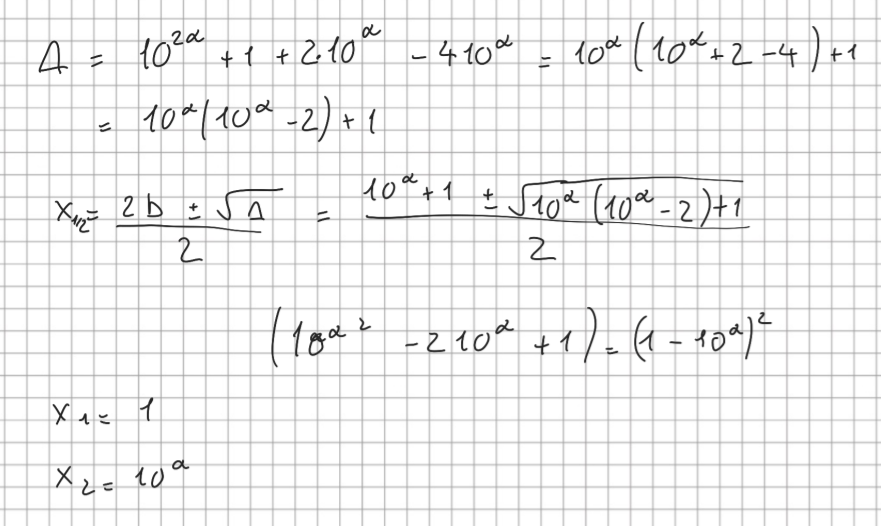

Gli errori di calcolo possono essere imputati alle approssimazioni di calcolo eseguite dal computer.

Esercizio 4 lezione

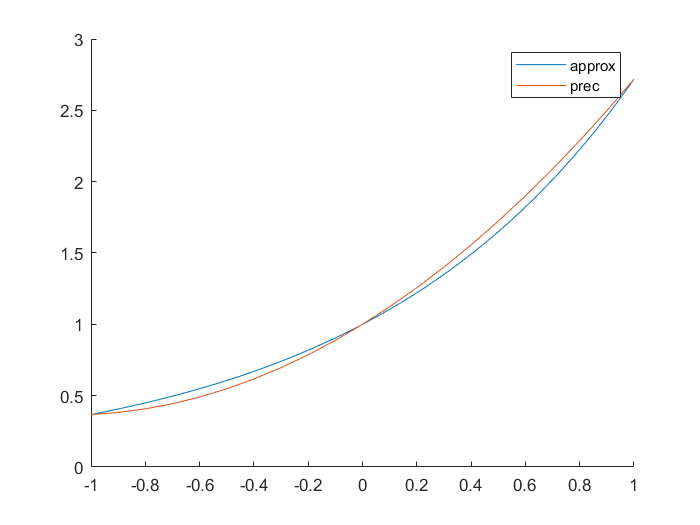

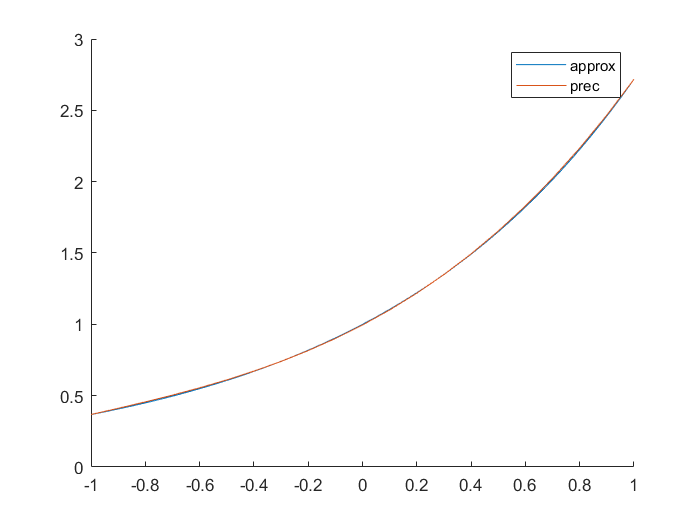

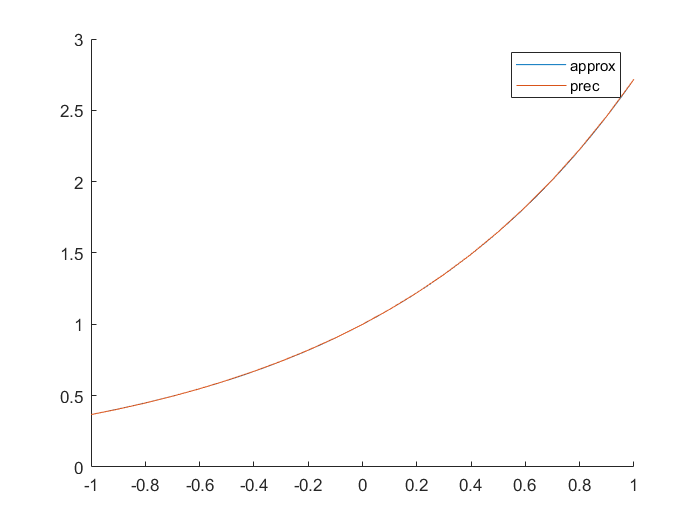

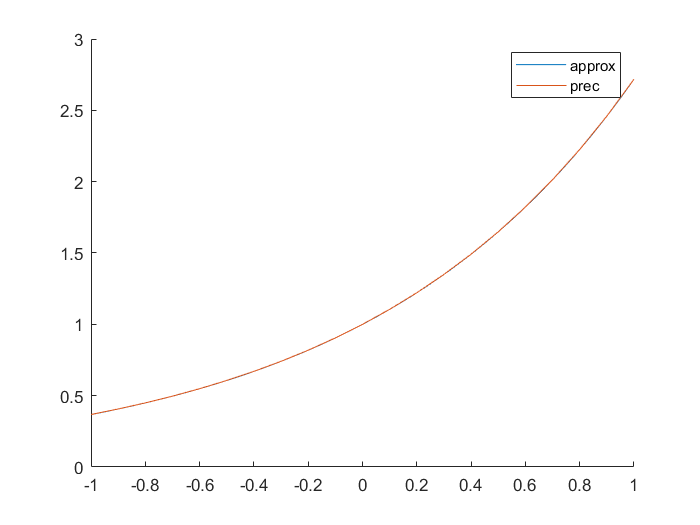

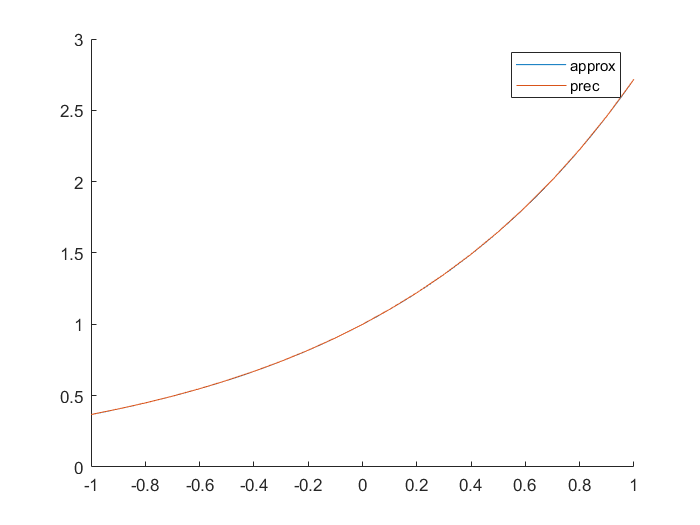

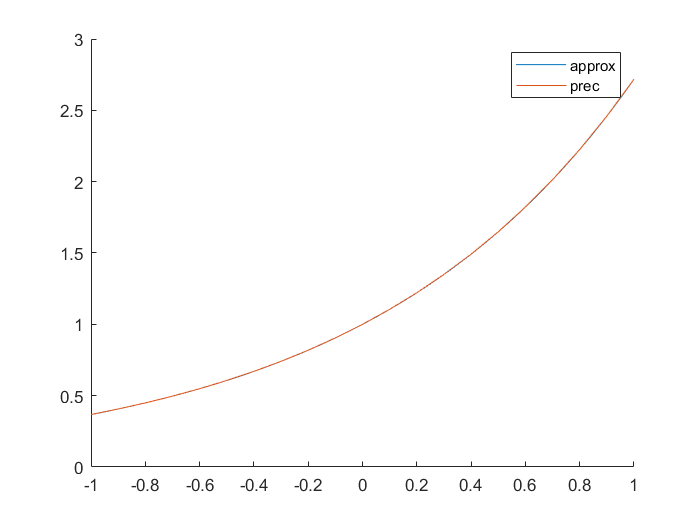

f=@(x) exp(x);
N=100;
n=linspace(-1,1,N);
fn=f(n);
for i=2:1:20
    figure()
    hold on
    fplot(f,[-1 1])
    x=linspace(-1,1,i+1);
    y=f(x);
    p=polyfit(x,y,i);
    x1=-1:0.1:1;
    y=polyval(p,x1);
    plot(x1,y)
    for c=1:1:N
        e(c)=abs(fn(c)-polyval(p,n(c)));
    end
    err1(i-1)=max(e);
    legend("approx","prec")
end

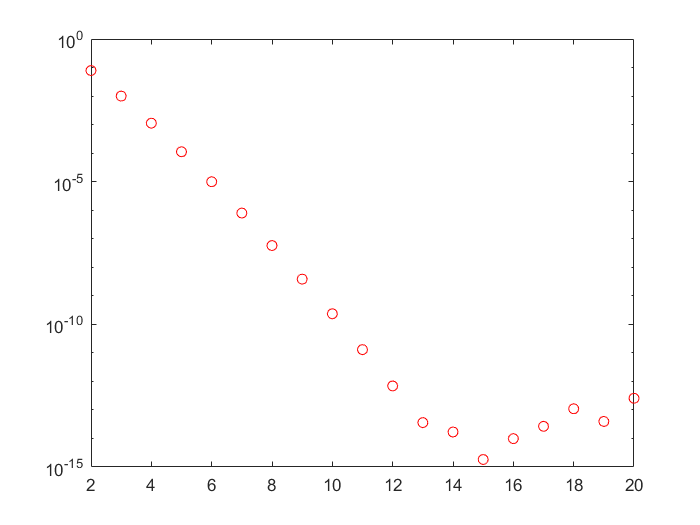

figure()
semilogy(2:20,err1,"or")

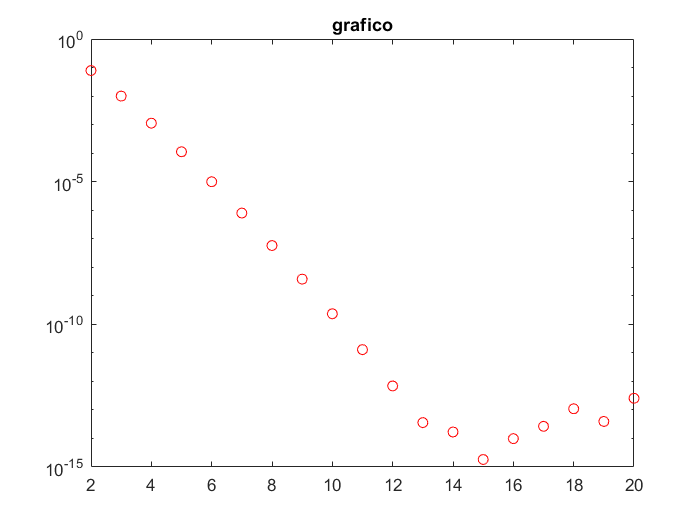

semilogySave({2:20},{err1},"grafico","","or")